# Q. 1.4.1

Amirhossein Mohammadi (810197689)

clc
clear
close all
rng(1)
dcl_init_

b_tx = bit_gen(pkt_size, k);
sym_idx = bi2de(b_tx, 'left-msb');
cons = nan;

[rx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name , pulse_gen_mode, mod_det_opt);

Es_avg = 1;
Eb = Es_avg/k;
ser = zeros(numel(snr_db), 1);
ber = zeros(numel(snr_db), 1);
ber_mat = zeros(numel(snr_db), 1);

for i = snr_min:snr_max %dB
    snr = i;
    var_noise = Eb/(10^(0.1*snr));
    noise_smpl = sqrt(var_noise/2)*randn(length(rx_smpl), 1) + 1i*sqrt(var_noise/2)*randn(length(rx_smpl), 1);
    h = sqrt(1/2)*(normrnd(0,1,[length(rx_smpl),1]) + 1i*normrnd(0,1,[length(rx_smpl),1])) ;
    rx_smpl_noise = rx_smpl + noise_smpl./h;
    new_rx_smpl = rx_smpl_noise;
    [det_sym_idx, rx_sym] = pulse_demodulation(new_rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name, rx_type, mod_det_opt);
    det_bit = flip(de2bi(det_sym_idx-1), 2);    
    det_bit = det_bit(1:size(b_tx, 1), :);
    ber(abs(snr_min) + i+1) = sum(det_bit ~= b_tx, 'all')/length(b_tx)/k;
end


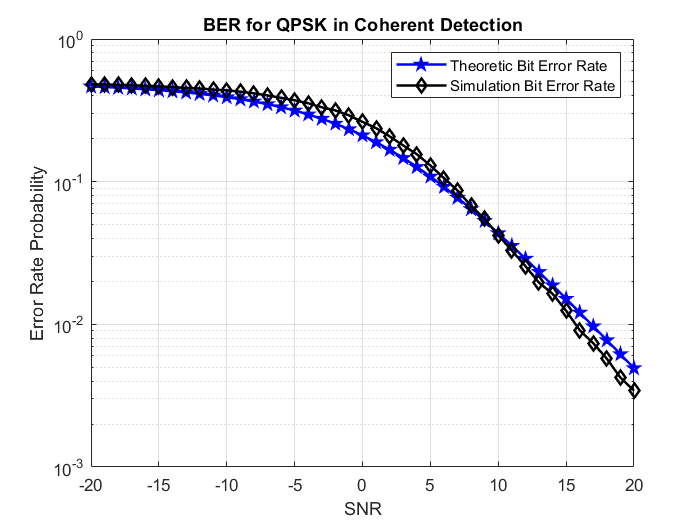


SNR_mag = 10.^(snr_db/10);
BER_QPSK = 0.5.*(1-sqrt(SNR_mag./(SNR_mag+2)));
semilogy(snr_db, BER_QPSK,'bp-', 'LineWidth',1.5);
hold on
semilogy(snr_db, ber, 'kd-','LineWidth',1.5)
grid on
title("BER for QPSK in Coherent Detection")
xlabel("SNR")
ylabel("Error Rate Probability")
legend( "Theoretic Bit Error Rate", "Simulation Bit Error Rate")

# Q. 1.4.2

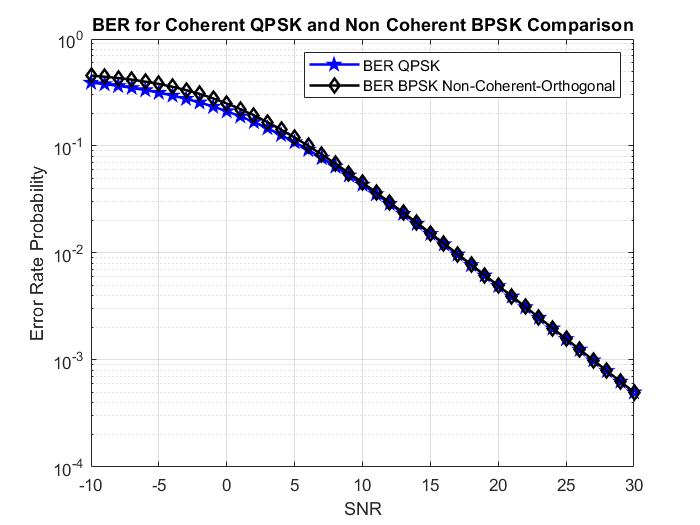

snr_db = -10:1:30;
SNR_mag = 10.^(snr_db/10);
BER_QPSK = 0.5.*(1-sqrt(SNR_mag./(SNR_mag+2)));
BER_BPSK_orth =  1./(2.*SNR_mag + 2);
figure
semilogy(snr_db, BER_QPSK,'bp-', 'LineWidth',1.5);
hold on
semilogy(snr_db, BER_BPSK_orth, 'kd-','LineWidth',1.5)
grid on
title("BER for Coherent QPSK and Non Coherent BPSK Comparison")
xlabel("SNR")
ylabel("Error Rate Probability")
legend( "BER QPSK", "BER BPSK Non-Coherent-Orthogonal")